clear all
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [9, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Node", "Nominal_stress", "X_heigth", "Ymm", "Var5"];
opts.SelectedVariableNames = ["Node", "Nominal_stress", "X_heigth", "Ymm"];
opts.VariableTypes = ["double", "double", "double", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Var5", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var5", "EmptyFieldRule", "auto");

% Import the data
tbl = readtable("Stress_data.csv", opts);


data = table2array(tbl)

data = 1.0e+03 *

    0.0010    0.0034    0.0037    0.0458
    0.0020    0.0032    0.0037    0.0458
    0.0030    0.0030    0.0036    0.0458
    0.0040    0.0028    0.0036    0.0458
    0.0050    0.0026    0.0035    0.0458
    0.0060    0.0025    0.0034    0.0458
    0.0070    0.0023    0.0034    0.0458
    0.0080    0.0022    0.0033    0.0458
    0.0090    0.0021    0.0032    0.0458
    0.0100    0.0020    0.0032    0.0458


Y_data = data(:,4)

Y_data =    45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700
   45.7700



% data3 = data((data(:,1)<N_D) && (data(:,3)==0))


Jeg sortere dataen så kun det der ligger præcis på linjen kommer med (45,77).

data_sort = [];
Y_line = 45.77

Y_line = 45.7700

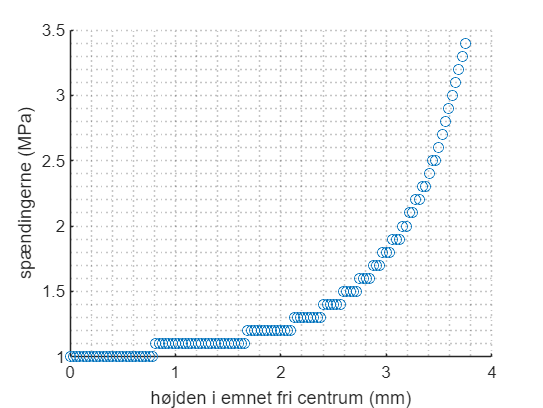


for i = 1:length(data(:,1))
    if Y_data(i) == Y_line
        data_sort(end+1,2:3) = data(i,2:3);
    end
end


sigma = data_sort(:,2);
x = data_sort(:,3);

scatter(x, sigma)
% plot(x, sigma)
xlabel("højden i emnet fri centrum (mm)")
ylabel("spændingerne (MPa)")
grid('minor')

F = 100; %N
A = pi*max(x)^2; % normal arealet på kraften
sigma_k = sigma %Fe spændingerne

sigma_k =     3.4000
    3.2000
    3.0000
    2.8000
    2.6000
    2.5000
    2.3000
    2.2000
    2.1000
    2.0000


sigma_n = F/A

sigma_n = 2.2635


K_t = sigma_k/sigma_n

K_t =     1.5021
    1.4137
    1.3254
    1.2370
    1.1486
    1.1045
    1.0161
    0.9719
    0.9278
    0.8836


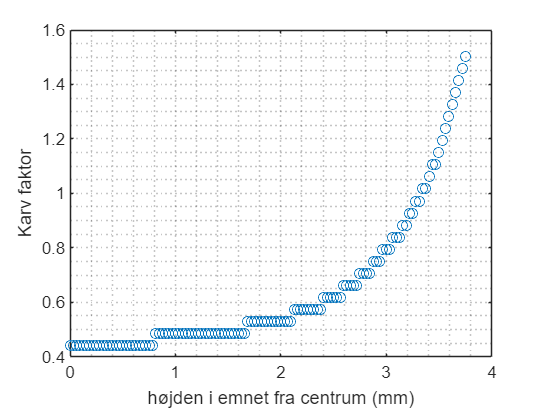

plot(x,K_t, 'o')
xlabel("højden i emnet fra centrum (mm)")
ylabel("Karv faktor")
grid('minor')


$$\chi^* = \left| \frac{\Delta\sigma}{\sigma_{k,max} \Delta x} \right|$$


% sigma_1_k = sigma(1)
dx = x(1) - x(2) % mindre x skridt afstand

dx = 0.0625

dS = sigma(1)/sigma(2)

dS = 1.0625

sigma(1)/max(sigma_k)

ans = 1

sigma(2)/max(sigma_k)

ans = 0.9412

X_grad = (sigma(1)/max(sigma_k) - sigma(2)/max(sigma_k))/((x(1) - x(2)))

X_grad = 0.9412

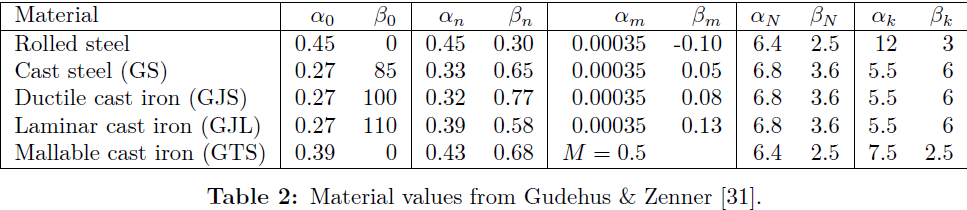

alpha_n = 0.32; 
beta_n = 0.77;
n = 1 + alpha_n * X_grad^beta_n

n = 1.3054

K_f = max(K_t)/n

K_f = 1.1507

sigma_R_smooth = 104.5 % MPa (for 𝑁𝐷=106 cycles).

sigma_R_smooth = 104.5000

sigma_R_notched = sigma_R_smooth/max(K_f)

sigma_R_notched = 90.8177

sigma_R_notched_real = 79.8; %MPa
procent_afvigelse = (sigma_R_notched - sigma_R_notched_real)/sigma_R_notched

procent_afvigelse = 0.1213

K_f_real = sigma_R_smooth/sigma_R_notched_real

K_f_real = 1.3095

n_real = max(K_t)/K_f_real

n_real = 1.1470

n

n = 1.3054

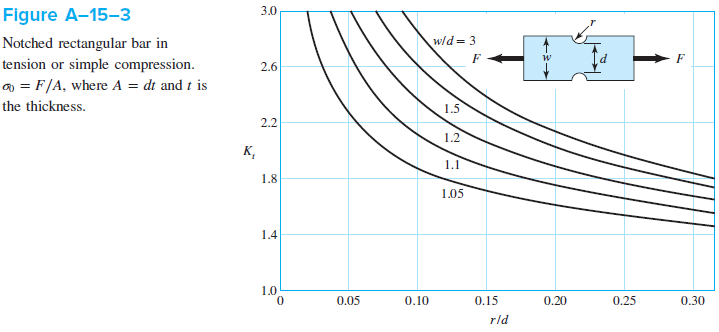

r = 2.25; %mm
d = 2*max(x) %mm

d = 7.5000


w = 12; %mm

rd = r/d

rd = 0.3000

wd = w/d

wd = 1.6000

K_t_shigleys = 1.75 

K_t_shigleys = 1.7500

max(K_t)

ans = 1.5021